Global Orbital Launch Defense

Shane Dirks and Nick Folz

AA279B Final Project

Spring of 2018

clear all;

fileID = fopen('vehicleinfo.txt','r');

x = textscan(fileID,'%s',1,'delimiter','\n\r');
header1 = cell2mat(x{1});
y = textscan(fileID,'%s',1,'delimiter','\n\r');
header2 = cell2mat(y{1});

data = cell2mat(textscan(fileID,'%f %f %f %f %f %f %f',3,'delimiter','/n/r'));
fclose('all');
clearvars fileID x y

vehicles = data(end,1);
R_vehicles_ECI = data(:,2:4);
V_vehicles_ECI = data(:,5:7);

days = 6574.5; %solar days between jan 1, 2000 12:00 until jan1 2018, 00:00
%per wolfram alpha
theta_epoch = mod((280.4606 + 360.9856473*days)/180*pi,2*pi); %in radians


% Define constants and stuff
R_earth = 6378.1;
omega_earth = 0.0000729211585530;%rad/sec per HW3
mu_earth = 398600.4418;
time_sim = 45.4*86400; %number of sec (days*86400) since epoch
tlength = 1*3600; %hours of simulation

tvec = time_sim:1:time_sim+tlength;
thetavec = mod((280.4606 + 360.9856473*tvec/86400)/180*pi,2*pi);
size_for_things = 100;

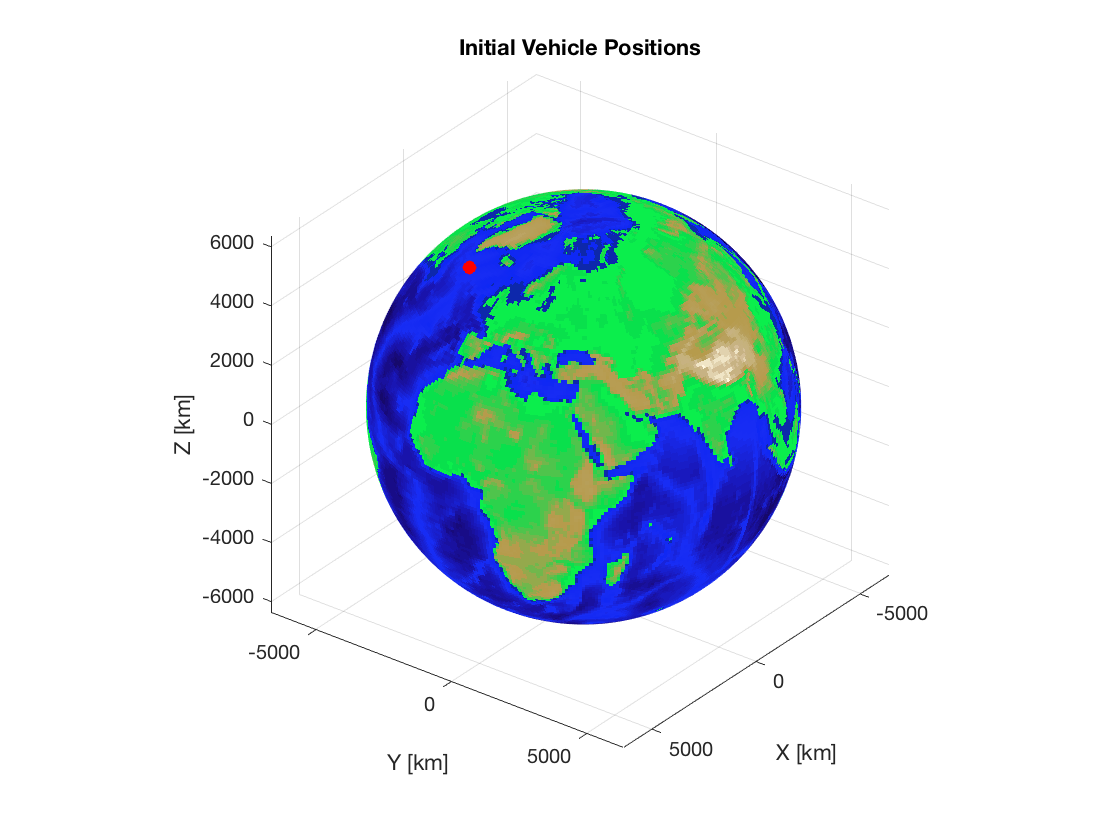

% Plot Initial Vehicle positions
if(1) 
    
figure
earth_sphere(size_for_things);
hold on
for i = 1:vehicles
[r,v] = ECI2ECEF(R_vehicles_ECI(i,:),V_vehicles_ECI(i,:),thetavec(1),omega_earth);
plot3(r(1),r(2),r(3),'or','MarkerFaceColor','r')
end
title('Initial Vehicle Positions')

end

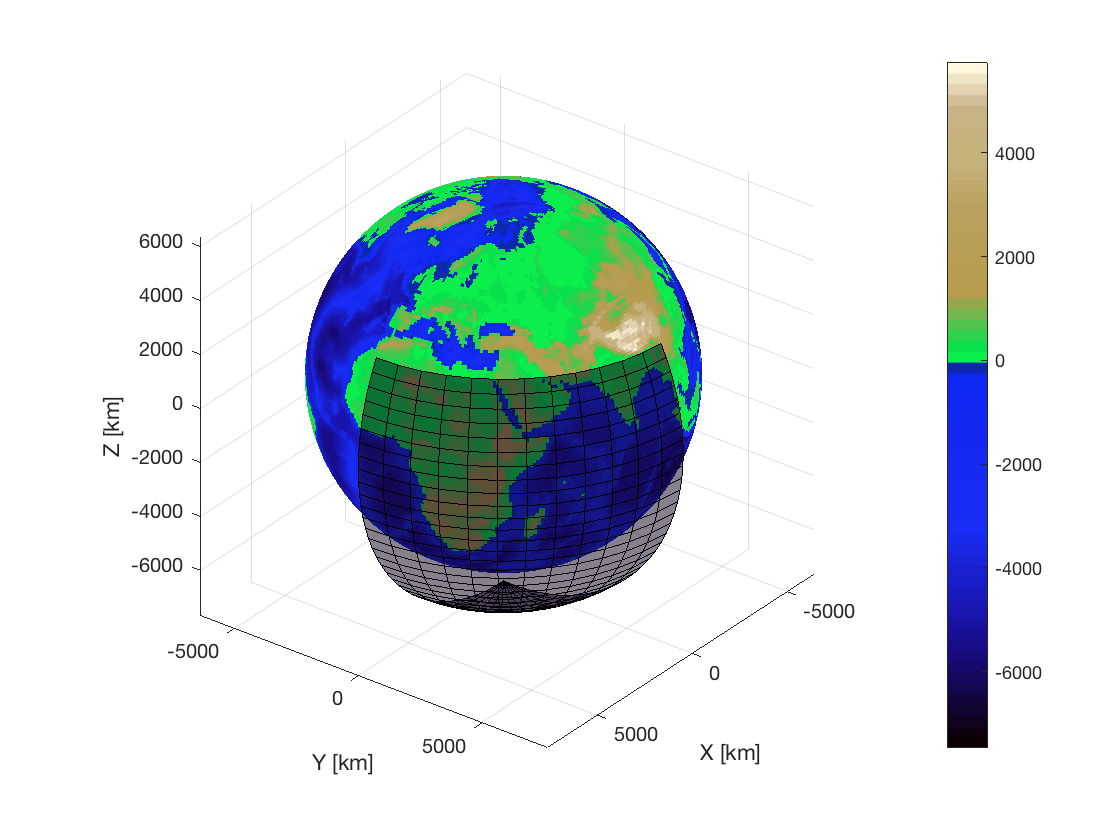

close all
figure
earth_sphere(size_for_things);

lim = caxis;
hold on
colorbar
[a,b,c] = sphere(size_for_things/2);

if 1
a = a*R_earth*1.2+0*R_earth;
A = a;
A(A<0) = NaN;

b = b*R_earth*1.2+0*R_earth;
B = b;
B(B<0) = NaN;
c = c*R_earth*1.2+0*R_earth;
C = c;
C(C>4/8*max(C)) = NaN;
end
%y = (y>0)*R_earth*1.2; z = (z>0)*R_earth*1.2;
surf(A,B,C,a.*0-7000,'FaceAlpha',.5)

%caxis = lim;
%earth_sphere(size_for_things);
max(max(c));

ans = 7.6537e+03

max(max(C));

ans = 3.6872e+03

caxis = lim;